## Segéd függvények

loglin = @(totalCount, f_floor, f_ceiling) ...
    f_floor .* (f_ceiling/f_floor) .^ ((0:(totalCount -1)) / (totalCount - 1));
% f = frekvencia; a = átmeneti függvény
phase_diff = @(f, a) atan2d(imag(a(f)), real(a(f)));
dampening_db = @(f, a) 20 * log10(abs(a(f)));

## 1. feladat

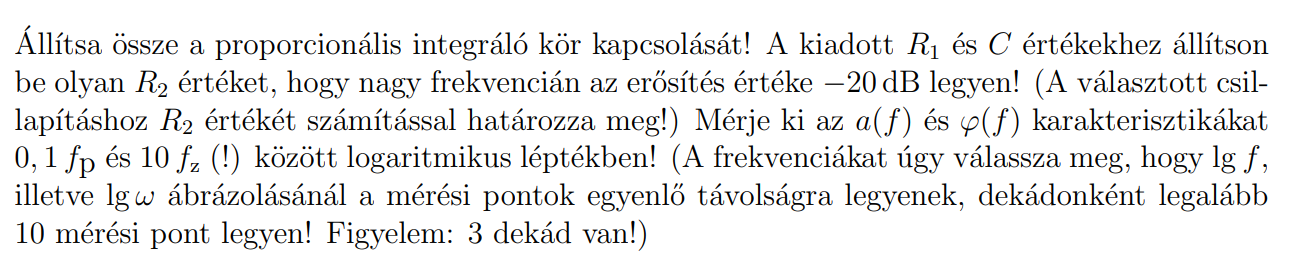

### Adatok

R_1 = 10 * 10^3;
C = 22 * 10^-9;
f_floor_multiplier = 0.1;
f_ceiling_multiplier = 10;
target_dampening_db = -20;

### Ellenállás meghatározása


$$\omega {\;}_z =\frac{1}{R_2 \cdot C},\;\;\omega {\;}_p =\frac{1}{\left(R_1 +R_2 \right)\cdot C}$$



$$a\left(\omega \;\right)=\frac{1+j\frac{\omega }{\omega {\;}_z }\;}{1+j\frac{\omega }{\omega {\;}_p }\;}$$


Ebből láthatjuk, hogy $R_2$kiszámítása egy adott frekvencián, mondjuk $\omega {\;}_t =10000$ lehetséges, mivel tudjuk, hogy 

f_target = 10000;


$$\begin{array}{l}
20\cdot \;\log \left(a\left(\omega {\;}_t \right)\right)\approx -20\textrm{dB}\\
20\cdot \;\log \left(\left|\frac{1+j\frac{\omega_t }{\omega {\;}_z }\;}{1+j\frac{\omega_t }{\omega {\;}_p }\;}\right|\right)=-20
\end{array}$$


A jegyzet alapján tudjuk, hogy ez ezzel egyenlő


$$\begin{array}{l}
20\cdot \;\log \left(\sqrt{\frac{1+\frac{\omega_t^2 }{\omega {\;}_z^2 }\;}{1+\frac{\omega_t^2 }{\omega {\;}_p^2 }\;}}\right)=-20\\
\log \left({\sqrt{\frac{1+\frac{\omega_t^2 }{\omega {\;}_z^2 }\;}{1+\frac{\omega_t^2 }{\omega {\;}_p^2 }\;}}}^{20} \right)=-20
\end{array}$$


Wolfram alpha megoldja innen


$$R_2 =1111,1$$


R_2 = 1111.1;

omega_cutoff = 1 / ((R_1 + R_2) * C);
f_cutoff = omega_cutoff / (2 * pi);
omega_dampen = 1 / ((R_2) * C);
f_dampen = omega_dampen / (2 * pi);
f_floor = f_floor_multiplier * f_cutoff;
f_ceil = f_ceiling_multiplier  * f_dampen;

### Maximum pont


$$\omega {\;}_{\max } =\sqrt{\;\omega {\;}_z \omega {\;}_p }$$


f_max = sqrt(f_cutoff * f_dampen);

### Mérés

effectation = @(f) (1 + 1i * ((f * 2 * pi) / (omega_dampen))) ...
    ./ (1 + 1i * ((f * 2 * pi) / omega_cutoff));

f_measure_count = 31;
f_measurements = loglin(f_measure_count, f_floor, f_ceil);

f_damp_calc = dampening_db(f_measurements, effectation);
f_phase_diff_calc = phase_diff(f_measurements, effectation);

f_damp_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];
f_phase_diff_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];

calced_val = table(f_measurements', f_damp_calc', f_phase_diff_calc', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);
disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 31×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            65.109             -0.042779      -5.1377 
            81.967             -0.067603      -6.4541 
            103.19              -0.10665      -8.0979 
            129.91              -0.16781      -10.141 
            163.55              -0.26299      -12.661 
            205.89              -0.40959      -15.737 
             259.2              -0.63204      -19.428 
            326.32              -0.96234       -23.75 
            410.81               -1.4382       -28.64 
            517.18               -2.0971       -33.92 
            651.09               -2.9671       -39.29 
            819.68               -4.0562      -44.364 
            1031.9               -5.3477      -48.744 
            1299.1               -6.8037      -5

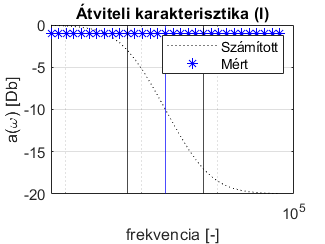


figure();
semilogx(f_measurements, f_damp_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_damp_mes, "b*");
xline(f_cutoff, "k");
xline(f_max, "b");
xline(f_dampen, "k");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

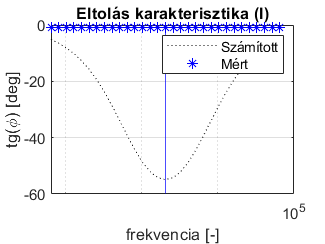


figure();
semilogx(f_measurements, f_phase_diff_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_phase_diff_mes, "b*"); 
xline(f_max, "b");
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])

### 2. feladat

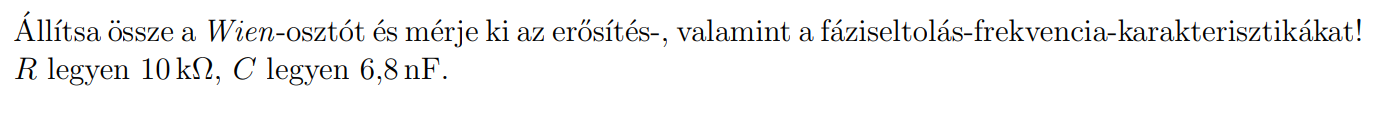

### Adatok

R = 10 * 10^3;
C = 6.8 * 10^-9;

### Számítás


$$Z_1 =R+\frac{1}{\textrm{jC}\omega \;},Z_2 =\frac{1}{\frac{1}{R}+\textrm{jC}\omega \;}$$



$$a\left(\omega \;\right)=\frac{Z_2 }{Z_1 +Z_2 }$$


Z_1 = @(f) R + (1 ./ (1i .* C .* f * 2 * pi));
Z_2 = @(f) 1 ./ ((1/R) + 1i .* C .* (f * 2 * pi));

effectation = @(f) Z_2(f) ./ (Z_1(f) + Z_2(f));

omega_passthrough = 1 / (R * C);
f_passthrough = omega_passthrough / (2 * pi);

### Mérések

f_floor = f_passthrough * 10^-2;
f_ceil = f_passthrough * 10^4;
f_measure_count = 31;

f_measurements = loglin(f_measure_count, f_floor, f_ceil);

f_damp_calc = dampening_db(f_measurements, effectation);
f_phase_diff_calc = phase_diff(f_measurements, effectation);

f_damp_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];
f_phase_diff_mes = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 ...
    -1];

calced_val = table(f_measurements', f_damp_calc', f_phase_diff_calc', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);
disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 31×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            23.405              -40.003        88.281 
            37.095              -36.008        87.277 
            58.791              -32.019        85.688 
            93.178              -28.048        83.179 
            147.68              -24.119         79.24 
            234.05              -20.294        73.142 
            370.95              -16.706        64.001 
            587.91              -13.601         51.19 
            931.78              -11.293        35.168 
            1476.8              -9.9607         17.64 
            2340.5              -9.5424             0 
            3709.5              -9.9607        -17.64 
            5879.1              -11.293       -35.168 
            9317.8              -13.601        -

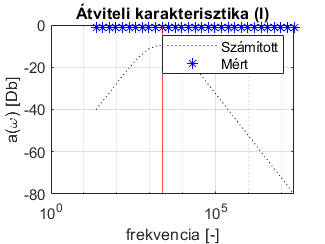


figure();
semilogx(f_measurements, f_damp_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_damp_mes, "b*");
xline(f_passthrough, "r");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

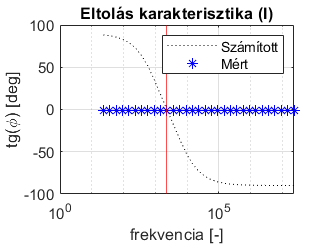


figure();
semilogx(f_measurements, f_phase_diff_calc, "k:"); hold on; grid on;
semilogx(f_measurements, f_phase_diff_mes, "b*"); 
xline(f_passthrough, "r");
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])